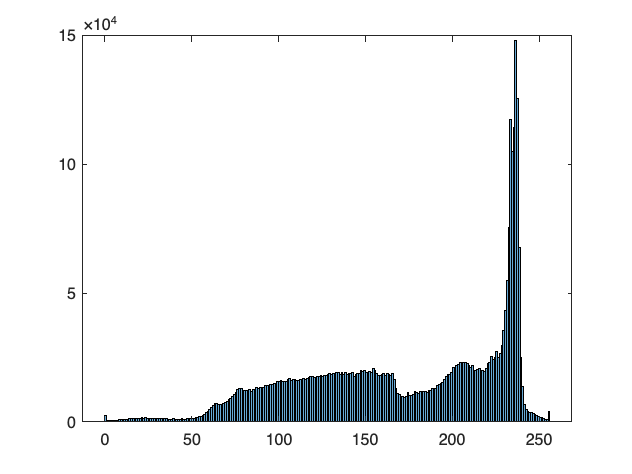

% Read the images
img1 = imread('Seattle_1.jpg');
img2 = imread('Seattle_2.jpg');

% Convert the images to grayscale if they are not
if size(img1, 3) == 3
    img1 = rgb2gray(img1);
end
if size(img2, 3) == 3
    img2 = rgb2gray(img2);
end

% Convert the images to binary format using Otsu's method
level1 = graythresh(img1);
bin_img1 = imbinarize(img1, level1);

level2 = graythresh(img2);
bin_img2 = imbinarize(img2, level2);

% Save the binary images
imwrite(bin_img1, 'Seattle1_binary.png');
imwrite(bin_img2, 'Seattle2_binary.png');

% Create and save histograms for the original images
figure;
histogram(img1(:), 'BinLimits', [0, 256], 'BinWidth', 1);
saveas(gcf, 'Seattle1_histogram.png');

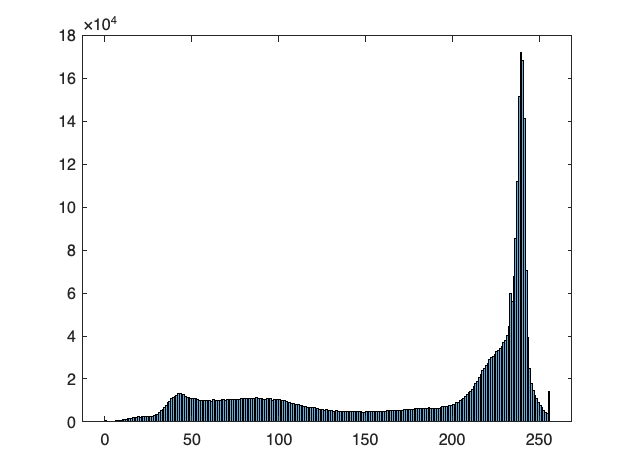


figure;
histogram(img2(:), 'BinLimits', [0, 256], 'BinWidth', 1);
saveas(gcf, 'Seattle2_histogram.png');

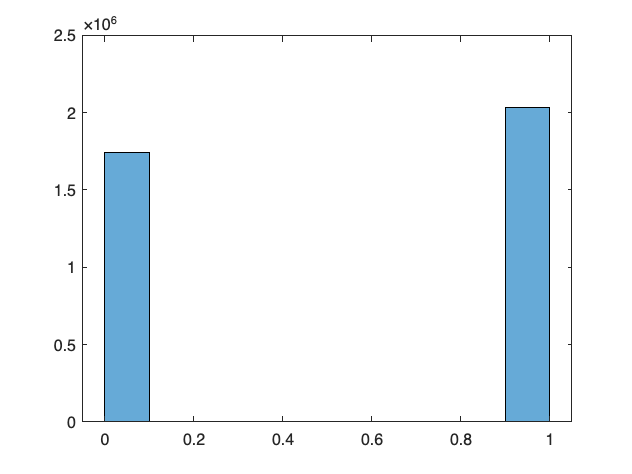


% Create and save histograms for the binary images
figure;
histogram(bin_img1(:), 'BinLimits', [0, 1], 'BinWidth', 0.1);
saveas(gcf, 'Seattle1_binary_histogram.png');

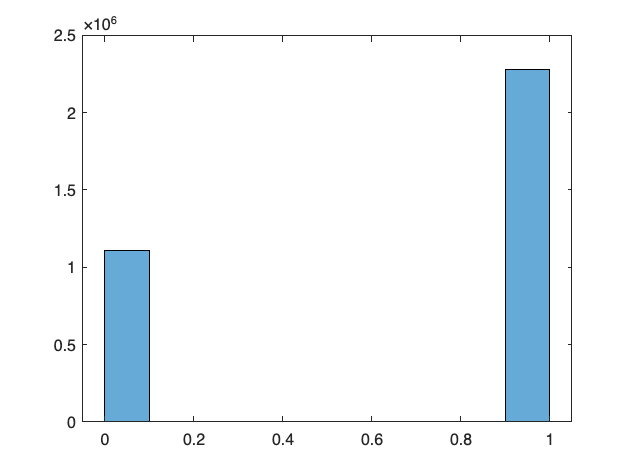


figure;
histogram(bin_img2(:), 'BinLimits', [0, 1], 'BinWidth', 0.1);
saveas(gcf, 'Seattle2_binary_histogram.png');


% Perform global thresholding on the original images
global_thresh_img1 = imbinarize(img1);
global_thresh_img2 = imbinarize(img2);

% Save the global thresholded images
imwrite(global_thresh_img1, 'Seattle1_global_thresh.png');
imwrite(global_thresh_img2, 'Seattle2_global_thresh.png');

% Define the threshold factor
thresholdFactor = 0.8; % Note** whiter if lower and blacker if higher

% Define the window sizes
window_sizes = [15, 30, 45];

% Process each image with each window size
for window_size = window_sizes
    % Initialize the thresholded images
    local_thresh_img1 = zeros(size(img1));
    local_thresh_img2 = zeros(size(img2));

    % Apply the local thresholding to each image
    for i = 1:window_size:size(img1, 1)
        for j = 1:window_size:size(img1, 2)
            % Extract the block
            block1 = img1(i:min(i+window_size-1, size(img1, 1)), j:min(j+window_size-1, size(img1, 2)));
            block2 = img2(i:min(i+window_size-1, size(img2, 1)), j:min(j+window_size-1, size(img2, 2)));

            % Calculate the local mean
            localMean1 = mean(block1(:));
            localMean2 = mean(block2(:));

            % Calculate the threshold
            T1 = localMean1 * thresholdFactor;
            T2 = localMean2 * thresholdFactor;

            % Apply the threshold
            local_thresh_img1(i:min(i+window_size-1, size(img1, 1)), j:min(j+window_size-1, size(img1, 2))) = block1 > T1;
            local_thresh_img2(i:min(i+window_size-1, size(img2, 1)), j:min(j+window_size-1, size(img2, 2))) = block2 > T2;
        end
    end

    % Convert the thresholded images to 8-bit images
    local_thresh_img1 = uint8(local_thresh_img1 * 255);
    local_thresh_img2 = uint8(local_thresh_img2 * 255);

    % Save the local thresholded images
    imwrite(local_thresh_img1, sprintf('Seattle1_local_thresh_%d.png', window_size));
    imwrite(local_thresh_img2, sprintf('Seattle2_local_thresh_%d.png', window_size));
end

% Define the structuring element
se = strel('disk', 1.0); % hmm this make it connect so if too connect -> lower 

% Process each image with each window size
for window_size = window_sizes
    % Initialize the thresholded images
    local_thresh_img1 = zeros(size(img1));
    local_thresh_img2 = zeros(size(img2));

    % Apply the local thresholding to each image
    for i = 1:window_size:size(img1, 1)
        for j = 1:window_size:size(img1, 2)
            % Extract the block
            block1 = img1(i:min(i+window_size-1, size(img1, 1)), j:min(j+window_size-1, size(img1, 2)));
            block2 = img2(i:min(i+window_size-1, size(img2, 1)), j:min(j+window_size-1, size(img2, 2)));

            % Calculate the local mean
            localMean1 = mean(block1(:));
            localMean2 = mean(block2(:));

            % Calculate the threshold
            T1 = localMean1 * 0.90;  % make text more bold if increase or blacker 
            T2 = localMean2 * 0.90;  % or more connect 

            % Apply the threshold
            local_thresh_img1(i:min(i+window_size-1, size(img1, 1)), j:min(j+window_size-1, size(img1, 2))) = block1 > T1;
            local_thresh_img2(i:min(i+window_size-1, size(img2, 1)), j:min(j+window_size-1, size(img2, 2))) = block2 > T2;
        end
    end

    % Convert the thresholded images to 8-bit images
    local_thresh_img1 = uint8(local_thresh_img1 * 255);
    local_thresh_img2 = uint8(local_thresh_img2 * 255);

    % Invert the binary images
    local_thresh_img1 = ~local_thresh_img1;
    local_thresh_img2 = ~local_thresh_img2;

    % Apply morphological operations
    local_thresh_img1 = imdilate(local_thresh_img1, se);
    local_thresh_img1 = imerode(local_thresh_img1, se);

    local_thresh_img2 = imdilate(local_thresh_img2, se);
    local_thresh_img2 = imerode(local_thresh_img2, se);

    % Invert the images back to the original representation
    local_thresh_img1 = ~local_thresh_img1;
    local_thresh_img2 = ~local_thresh_img2;

    % Save the local thresholded images
    imwrite(local_thresh_img1, sprintf('Improve_Seattle1_local_thresh_%d.png', window_size));
    imwrite(local_thresh_img2, sprintf('Improve_Seattle2_local_thresh_%d.png', window_size));
end